clear
clc

% Angles of attack.
alpha_list = [2 4 6];
% Mach numbers.
mach_list = [0.80 0.90 1.00 1.20 1.40];
% Annotation text.
annot_txt = ["$ \alpha = 2^{\circ} $", "$ \alpha = 4^{\circ} $", "$ \alpha = 6^{\circ} $"];
% Legend line names.
lables = ["$ M = 0.8 $", "$ M = 0.9 $", "$ M = 1.0 $", "$ M = 1.2 $", "$ M = 1.4 $"];
% Colors.
% deep blue: #406aa4, sky blue: #50a7d3, green: #80c34a, gold: #f3af16, red: #ec2f28, magenta: #e62e90
colors = ["#406aa4", "#80c34a", "#f3af16", "#ec2f28", "#e62e90"];

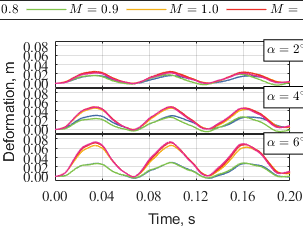

% Axis bounds.
x_bounds = [0,0.20];
y_bounds = [-0.01,0.09];

% Create layout.
t = tiledlayout(3,1,"TileSpacing","none",Padding="tight");

% Loop over angles of attack.
ax = gobjects(size(alpha_list));
for ia = 1:length(alpha_list)

    ax(ia) = nexttile;
    set(gca,'FontSize',11)
    
    % Loop over Mach numbers get lines.
    for im = 1:length(mach_list)
        hold on

        [x,~,y] = import_disp(alpha_list(ia),mach_list(im),'zDisp','wingtip',1.00);
        plot(x,y,LineWidth=1,Color=colors(im));
        
        hold off
    end


    % Text annotation.
    txt_text = text(0.9,0.8,annot_txt(ia),Units="normalized",BackgroundColor='white',Interpreter='latex',FontSmoothing='on',EdgeColor='k',Margin=2);
        
    % Axis limits.
    xlim(x_bounds);
    ylim(y_bounds);

    % Ticks.
    xticks(x_bounds(1):0.04:x_bounds(2));
    yticks(0:0.02:y_bounds(2));
    xtickformat(ax(ia),'%.2f');
    ytickformat(ax(ia),'%.2f');
    if ia ~= length(alpha_list)
        ax(ia).XAxis.TickLabels = cell(size(ax(ia).XAxis.TickLabels));
    end
    
    % Box.
    box on
    
    % Grid.
    grid on
end

% Labels.
t.XLabel.String = "Time, s";
t.YLabel.String = "Deformation, m";
t.XLabel.FontSize = 11;
t.YLabel.FontSize = 11;

% Legend.
lgd = legend(ax(1),lables,'Location','NorthOutside','Orientation','Horizontal',Interpreter='latex',FontSize=10);
lgd.Layout.Tile = 'North';

% Font formatting.
fontname(gcf,'Times New Roman')

exportgraphics(t,"C:\Users\jackh\OneDrive\MATLAB\aeroelasticity_research\onera-m6-modified\graphs\Mod. Winglet, Transient Deflection.png",'Resolution',600)